## **Lab 10**

## **Abdullah Ahmed **

## **aa09303**

**Task 1a)**

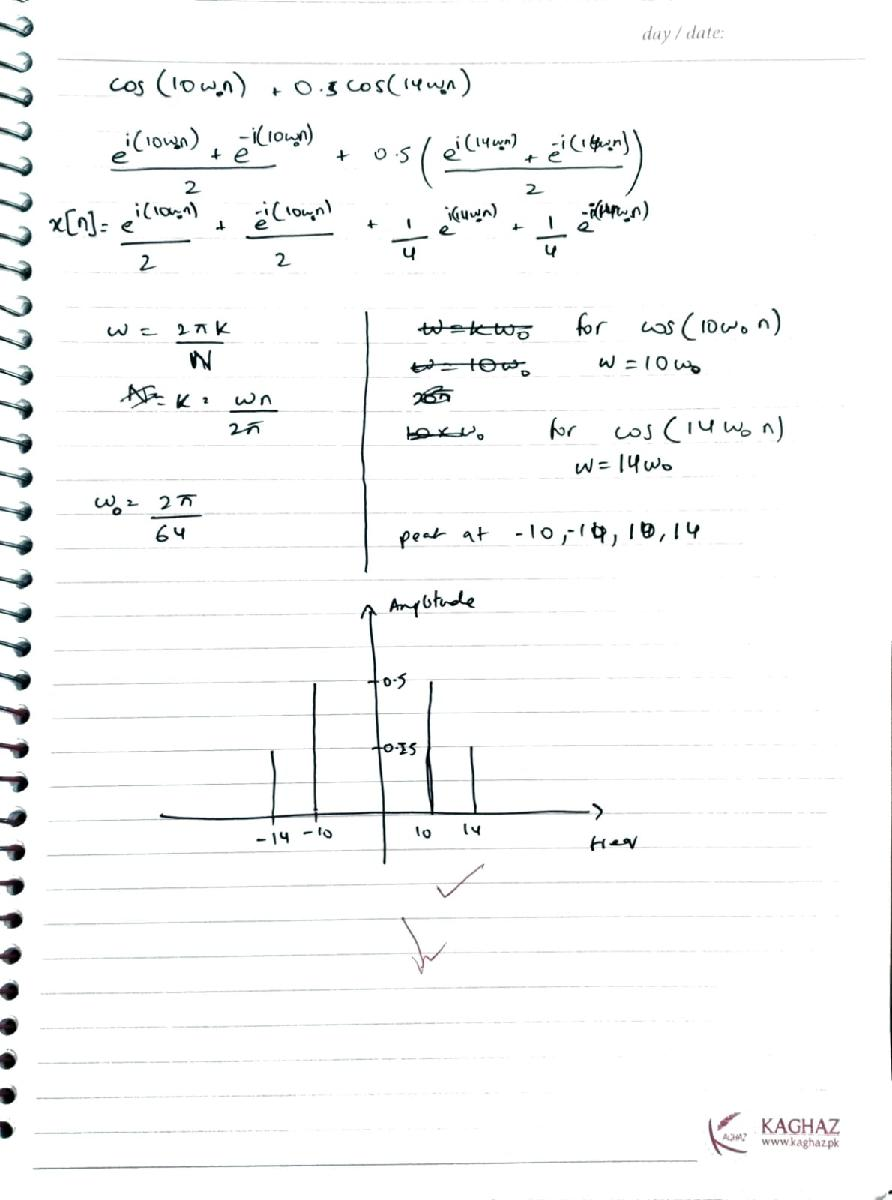

**Task 1b)**

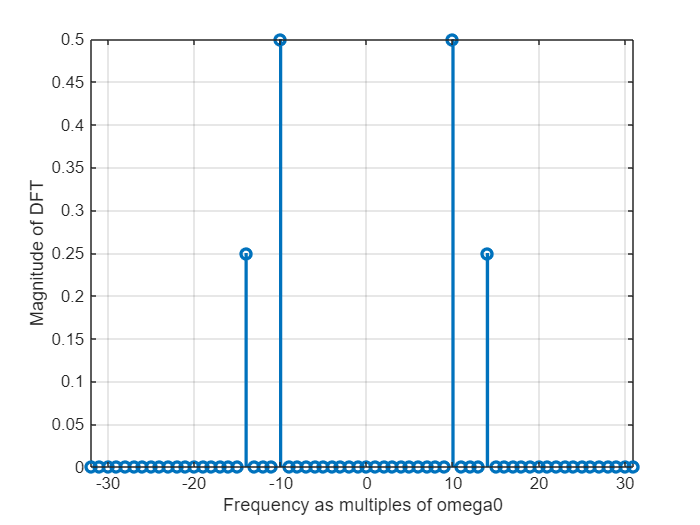

P = 64;
w = 2*pi/P;
n = 0:P-1;

x = cos(10 * w * n) + 0.5 * cos(14 * w * n);
hx = fft(x);
shx = fftshift(hx);
stem(-P/2:P/2-1, abs(shx)/P, 'LineWidth', 2);
ylabel('Magnitude of DFT');
xlabel('Frequency as multiples of omega0');
axis([-P/2 P/2-1 0 inf]);
grid;

**Task 2)**

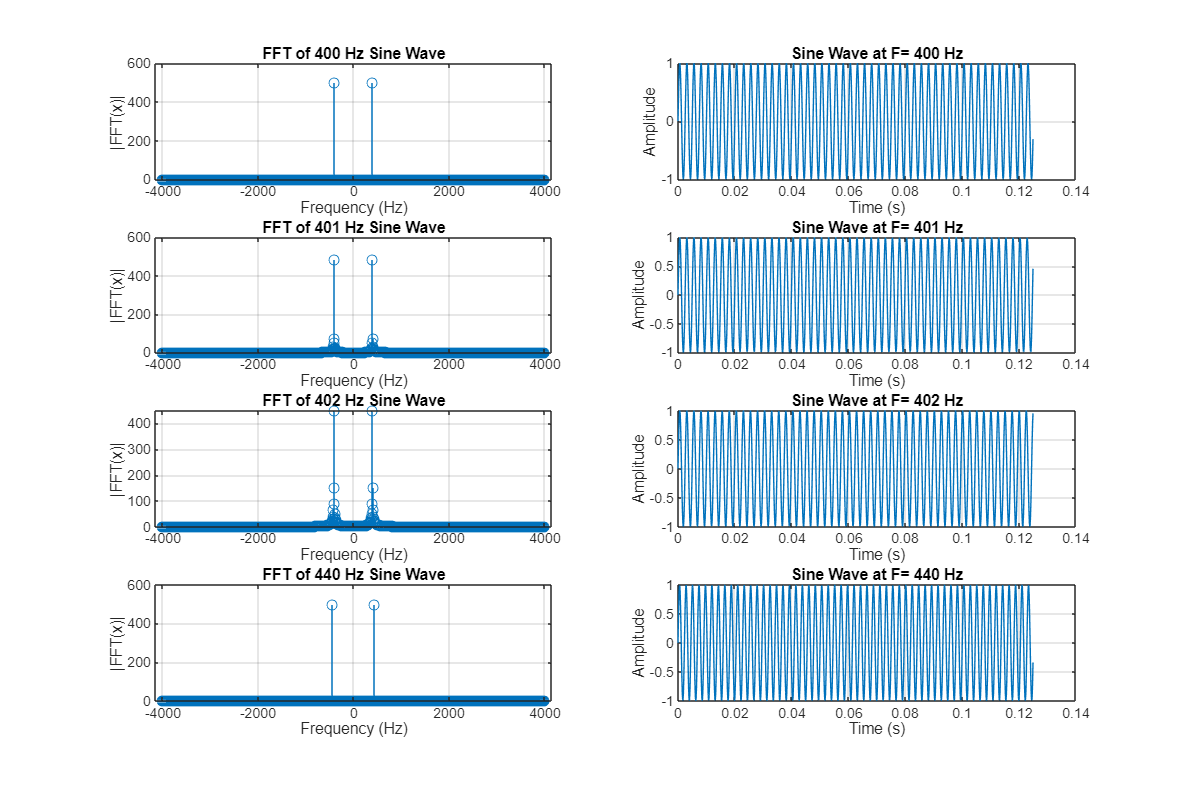

clc;
clear;
close all;
% Parameters
Fs = 8000;      % Sampling frequency
N = 1000;       % Number of samples
frequencies = [400, 401, 402, 440];  % Frequencies to analyze
i = 1;
figure;
set(gcf, 'Position', [100, 100, 1200, 800]);

for f0 = frequencies
    % Time vector
    t = (0:N-1)/Fs;

    % Generate sine wave
    x_t = sin(2 * pi * f0 * t);

    hx = fft(x_t, N);
    hx_shifted = fftshift(hx);

    % Generate frequency axis
    fHz = (-N/2:N/2-1) * (Fs/N);
    
    subplot(4,2,i)
    stem(fHz, abs(hx_shifted));
    xlabel('Frequency (Hz)');
    ylabel('|FFT(x)|');
    title(['FFT of ', num2str(f0), ' Hz Sine Wave']);
    grid on;

    subplot(4, 2, i+1); 
    plot(t, x_t); 
    xlabel('Time (s)'); 
    ylabel('Amplitude'); 
    title(['Sine Wave at F= ', num2str(f0), ' Hz']); 
    grid on;

    i = i + 2;
end

Observation1:

Yes, the result aligns with the steps we followed, where we sampled a sine wave and plotted it to ensure proper alignment along both the x and y axes.

Observation 2:

We observe that for both 440 Hz and 400 Hz, there is no frequency leakage, resulting in a perfect straight line. The sine waves for both frequencies appear identical because the ratio of the sampling frequency to the signal frequency produces an integer for 400 Hz (8000/400 = 20), leading to a leakage-free FFT. Although 440 Hz does not yield a perfect integer ratio (8000/440 = 18.18), the sine waves for both 400 Hz and 440 Hz remain similar. Additionally, the 440 Hz wave appears periodic with a slight mismatch.

Observation 3:

By increasing N, only the 400 Hz plot remains free of leakage. A higher N improves frequency resolution, resulting in a cleaner and smoother FFT.

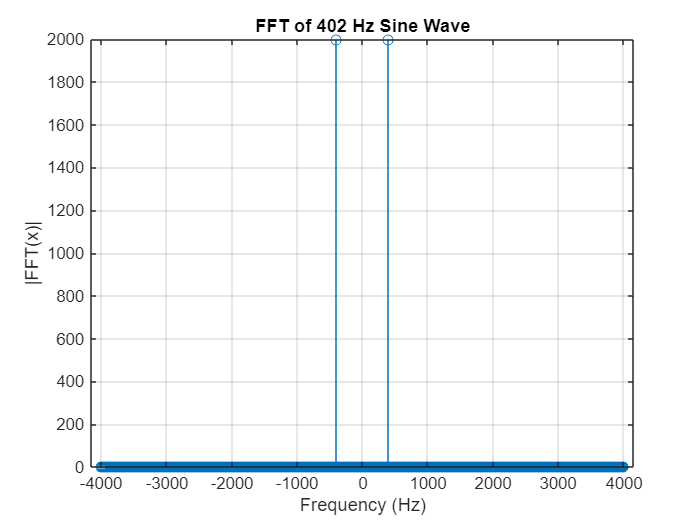

Fs = 8000;      % Sampling frequency
N = 4000;       % Number of samples
f0 = 402;  % Frequencies to analyze


figure;
t = (0:N-1)/Fs;
x_t = sin(2 * pi * f0 * t);

hx = fft(x_t, N);
hx_shifted = fftshift(hx);
fHz = (-N/2:N/2-1) * (Fs/N);

stem(fHz, abs(hx_shifted));
xlabel('Frequency (Hz)');
ylabel('|FFT(x)|');
title(['FFT of ', num2str(f0), ' Hz Sine Wave']);
grid on;

Observation 4:

Increasing the number of samples to 400 results in a smoother FFT. While the waveform may still not be perfectly periodic, the pattern becomes more noticeable over a longer duration.

**Task 3**

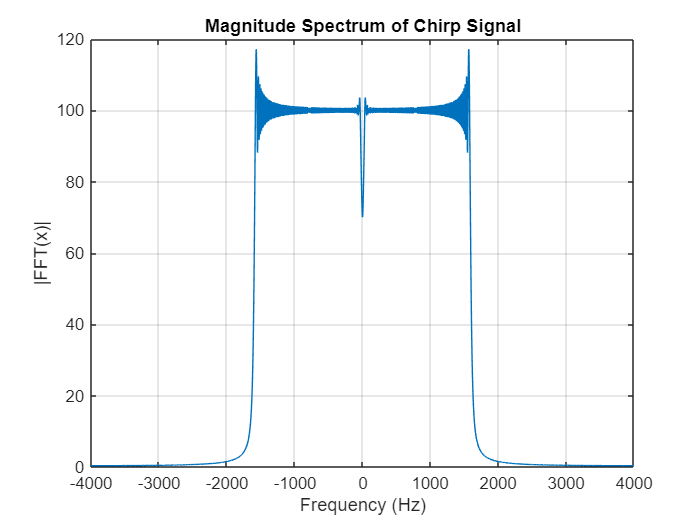

clc;
clear;
close all;
% 1)
fs = 8000;            
n_samples = 8000;     
t = (0:n_samples-1)/fs; 

x_n =  sin(2*pi*800*t.^2);

% 2)
N = 8192;  
X_f = fft(x_n, N); 
X_f_shifted = fftshift(X_f);

fHz = (-N/2:N/2-1) * (fs/N);

figure;
plot(fHz, abs(X_f_shifted));
xlabel('Frequency (Hz)');
ylabel('|FFT(x)|');
title('Magnitude Spectrum of Chirp Signal');
grid on;

Observation:

The flat region in the middle of the plot indicates that the signal contains a range of frequencies, while the sharp drops at the edges represent the starting and ending frequencies of the chirp. Additionally, the symmetry in the plot is expected since it is a characteristic feature of the FFT when applied to a signal.

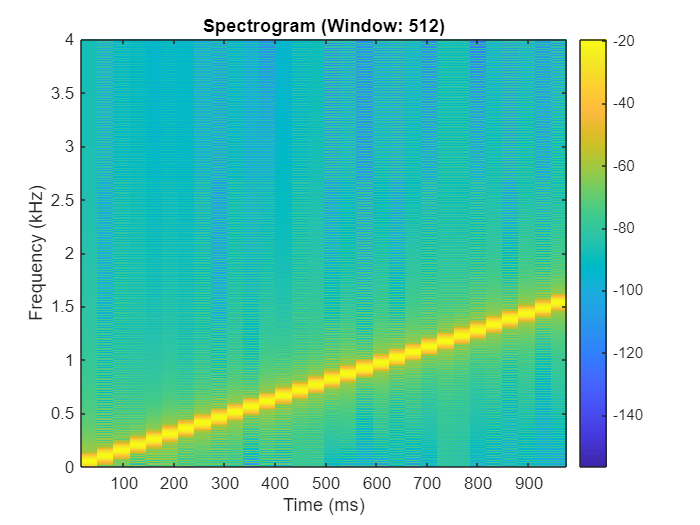

% 3)
figure;
spectrogram(x_n, 512, [], 1024, fs, 'yaxis');
title('Spectrogram (Window: 512)'); 
colorbar;

Observation:

The frequency increases linearly over time, matching our original plot, while the different colors indicate the power of various frequency components.

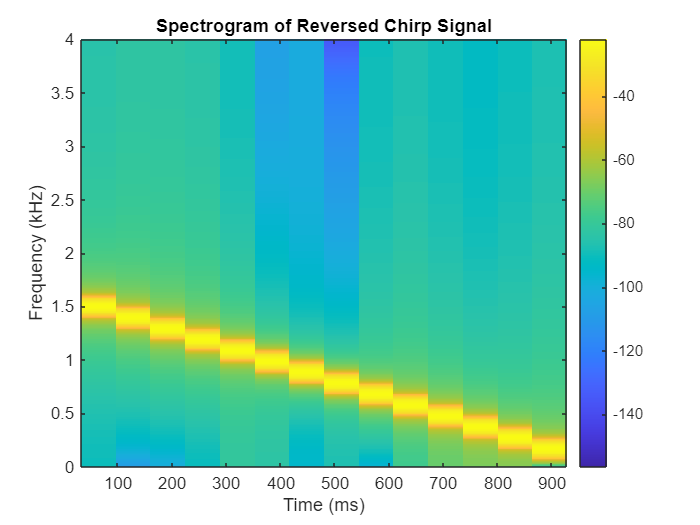

% 4)
x_reversed = x_n(8000:-1:1);  % Reverse the signal

figure;
spectrogram(x_reversed, 1024, [], 1024, fs, 'yaxis');
title('Spectrogram of Reversed Chirp Signal');
colorbar;

Observation:

The spectrogram accurately demonstrates that reversing the time-domain signal results in a flipped frequency representation.